# **Example of integral calculus**

In this example, we compute the center of mass and the kinetic momentum of a plate with holes and non uniform mass density.

We define the following plate:

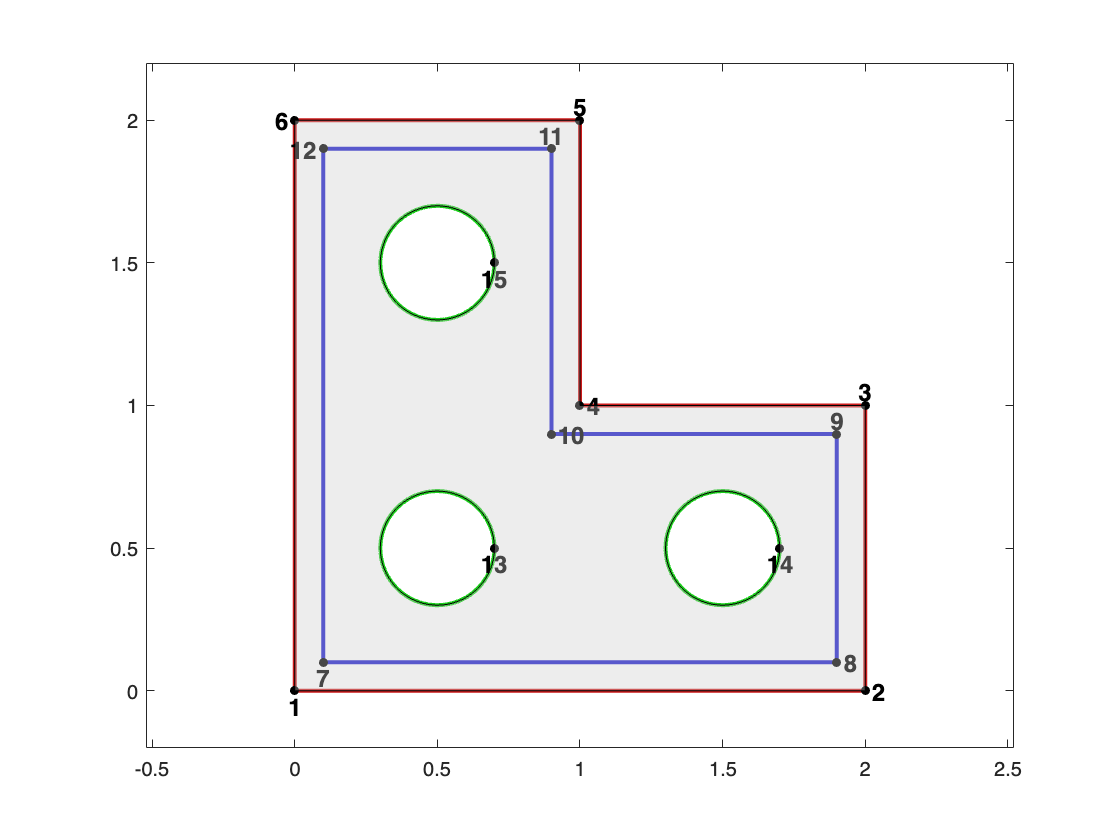

h = 0.1;
nodes = [0 0 ; 2 0 ; 2 1 ; 1 1 ; 1 2 ; 0 2 ; ...
         h h ; 2-h h ; 2-h 1-h ; 1-h  1-h ; 1-h 2-h ; h 2-h ; ...
         .7 .5 ; 1.7 .5 ; 0.7 1.5];
edges = {{1,2},{2,3},{3,4},{4,5},{5,6},{6,1},...
         {7,8,'lr'},{8,9,'lr'},{9,10,'lr'},{10,11,'lr'},{11,12,'lr'},{12,7,'lr'},...
         {13,13,'0.5+0.2*cos(t)','0.5+0.2*sin(t)',[0,2*pi],'r'},...
         {14,14,'1.5+0.2*cos(t)','0.5+0.2*sin(t)',[0,2*pi],'r'},...
         {15,15,'0.5+0.2*cos(t)','1.5+0.2*sin(t)',[0,2*pi],'r'},...
         };
domain = Domain(nodes,edges);
domain.plot('nodelabels');

endowed with a non uniform surface mass density $\rho \left(x,y\right)$ equal to 1 inside the blue domain and 3 outside. We mesh this domain at a resolution $h=0\ldotp 05$:

mesh = Mesh(domain,0.05)

building mesh
building mesh properties
done


mesh = Mesh object
nodes :           1950
triangles :       3666
h (input) :       0.05
h_bound (input) : 0.05
min edge size :   0.020475
max edge size :   0.063024
mean edge size :  0.041026
edge size std :   0.0070338
min quality :     0.73555
mean quality :    0.9539
memory (kB) :     1740
Build time (s) :  0.19
 

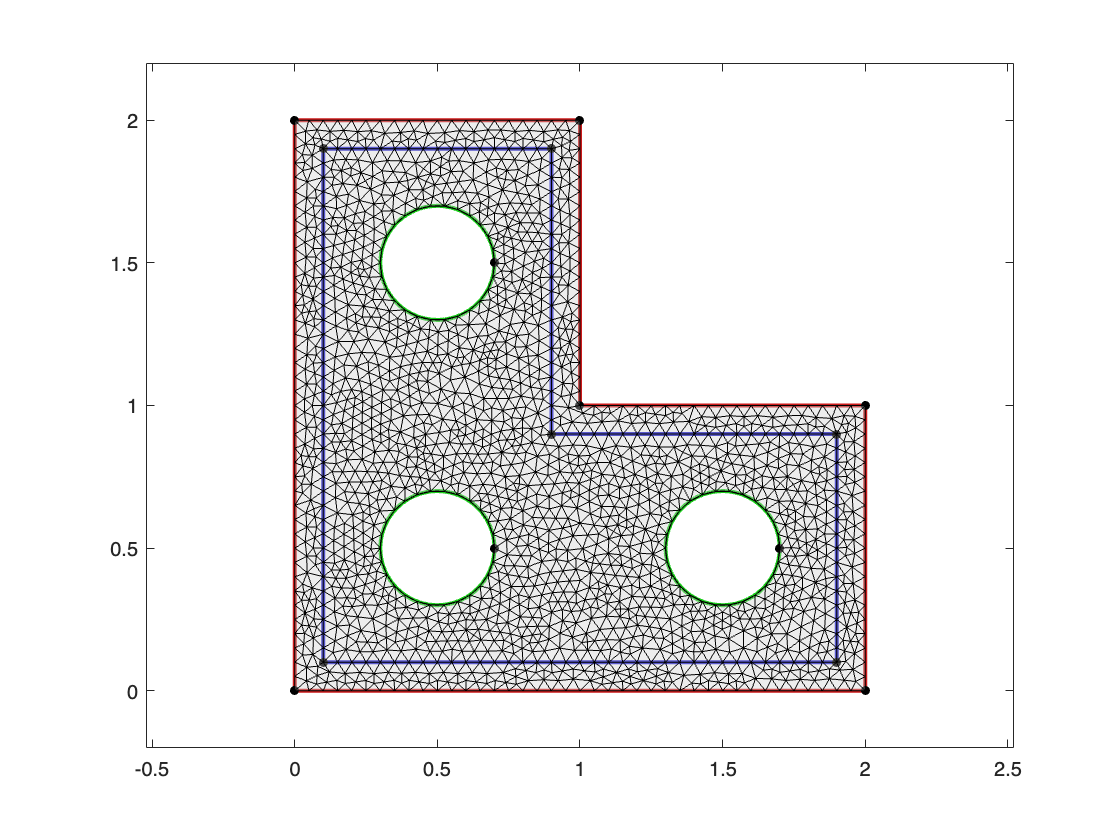

mesh.plot;

and then define the mass density function $\rho$:

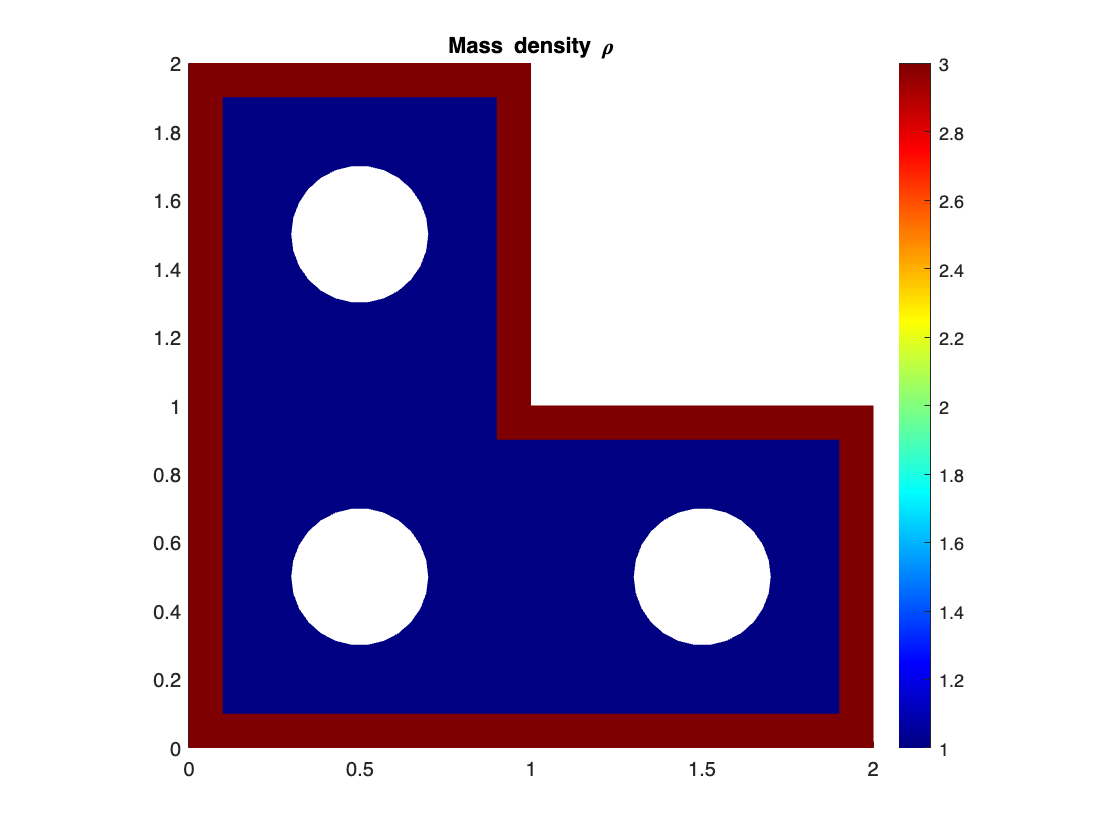

D = @(x,y) (x>h & x<2-h & y>h & y<1-h) | (x>h & x<1-h & y>h & y<2-h);
rho = @(x,y)  1*D(x,y) + 3*(1-D(x,y));
rhoP0 = mesh.P0(rho);
mesh.image(rhoP0);
title('Mass density \rho')

We can now compute the total mass of the plate:

m = mesh.integral(rho)

m = 4.1467

and the center of mass $\mathit{\mathbf{g}}$. For that we define the vector field $\mathit{\mathbf{v}}\left(x,y\right)=\rho \left(x,y\right)\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack$

and then compute the center of mass $\mathit{\mathbf{g}}=\frac{1}{m}\int_{\Omega } \mathit{\mathbf{v}}\left(x,y\right)\mathrm{dxdy}$.

v = @(x,y) [x.*rho(x,y) y.*rho(x,y)];
g = mesh.integral(v)/m

g =     0.8462    0.8462


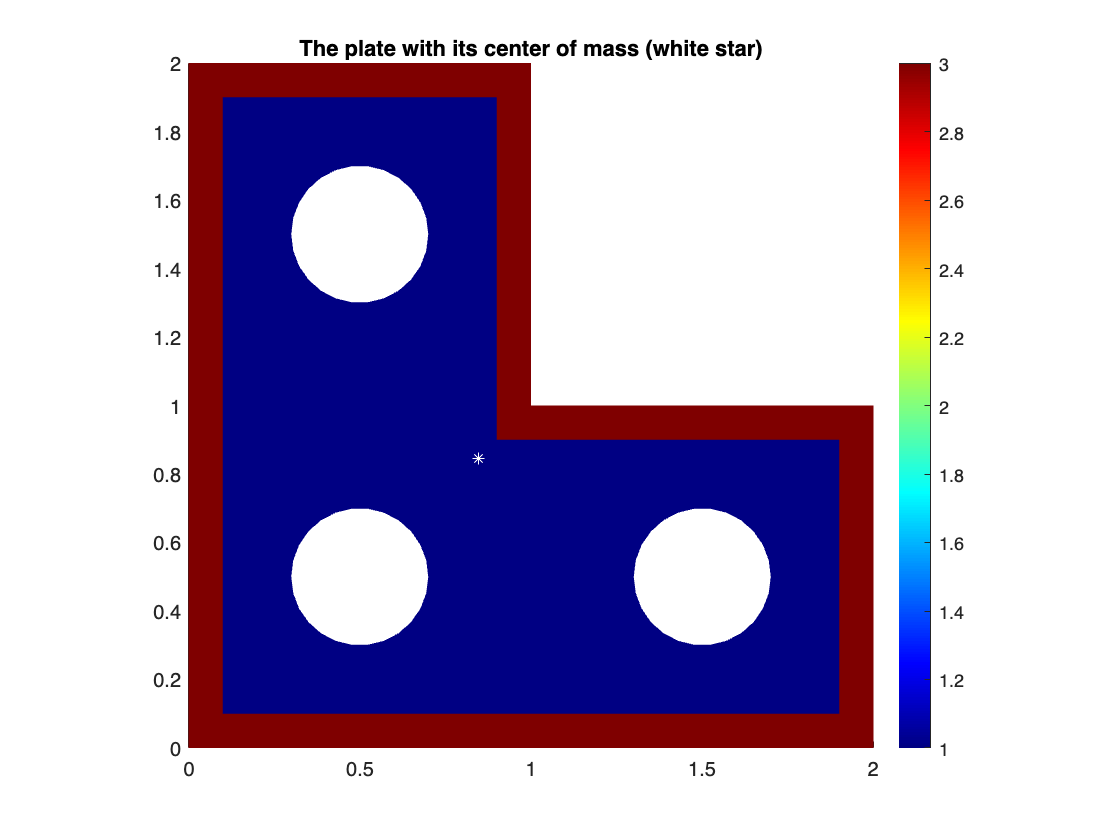

mesh.image(rhoP0);
hold on
plot(g(1),g(2),'w*')
title('The plate with its center of mass (white star)')

Finally we compute its inertia momentum with respect to its center of mass. The formula is


$$J=\;$$

$$\int_{\Omega } \left({\left(x-g_1 \right)}^{\;2} +{\left(y-g_2 \right)}^{\;2\;} \right)\rho \left(x,y\right)\mathrm{dxdy}$$


f = @(x,y) ((x-g(1)).^2 + (y-g(2)).^2).*rho(x,y);
J = mesh.integral(f)

J = 3.0839